# PARCISER - Projet 6.1 

## Génération de données simulées d'une SER

Le but est ici de se familiariser avec les données susceptibles d'être en sortie de l'analyseur de réseau, lors d'une série d'acquisition de la chambre anéchoïque de l'ENSTA.

La fonction gen_synth.m m'a été gracieusement donnée par le Dr. Comblet. Elle nécessite de poser plusieurs variables :

%xs = [ones(1,10) (1:10) 10*ones(1,10) (10:-1:1) 5.5];
%ys =  [(1:10) 10*ones(1,10) (10:-1:1) ones(1,10) 5.5];

xs = [-4 -2 0 0 0 0 2 3 3];
ys = [0 0 -3 -1 1 3 0 -2 2];  %Vu dans le poly de Mr Kenchaf

amps = 10.^[2*ones(1,length(xs)-1) 3];
map = [xs; ys ; amps];  %Coordonnées des points brillants


Il faudra vérifier quelle est l'unité des distances à fournir à map, pour que cela soit cohérent. Se rappeler aussi que la résolution en distance dépend de la largeur de bande. Ne pas prendre des points brillants dont la distance est inférieure à la résolution !

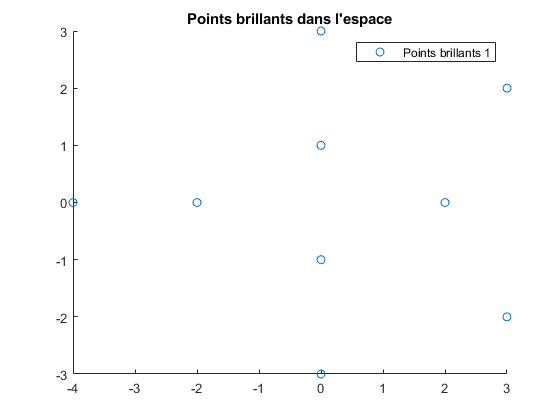

figure;
hold on
scatter(map(1,:),map(2,:),'DisplayName',"Points brillants 1")
%scatter(map2(1,:),map2(2,:),'DisplayName',"Points brillants 2")
title("Points brillants dans l'espace")
legend
hold off



fmin = 10e9; fmax = 11e9; % fmin et fmax
th1 = 0; th2=360;  %angle min et max

nf = 1000; nth = 5*360; %Nombre d'échantillons respectivement en angle, et en fréquence.

Ces variables sont posées en fonction des informations données par la page 15 de *Mesure de la SER*) 

Voyons ce que nous pouvons en faire.

sigc = gpuArray(gen_synth(map,fmin,fmax,nf,th1,th2,nth));  %Permet de faire les calculs sur le GPU, plus rapide.

sigc est une matrice de nf lignes, et nth colonnes.

Représentons la : 

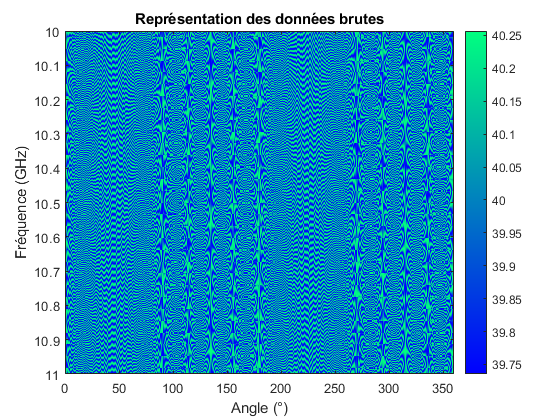

figure
imagesc(linspace(th1,th2,nth),linspace(fmin/1e9,fmax/1e9,nf),20*log10(abs(sigc)));  % Notons bien que là, j'ai mis les angles, puis les fréquences, sciemment.
colormap winter
colorbar
title('Représentation des données brutes')
xlabel('Angle (°)')
ylabel('Fréquence (GHz)')

Sur la figure ci-dessus, on obtient énormément de mesures, mais on va se limiter à une partie des angles, et passer hors du domaine fréquentiel. (IFFT)

Nous allons prendre, par exemple, les données entre 0° et 20°

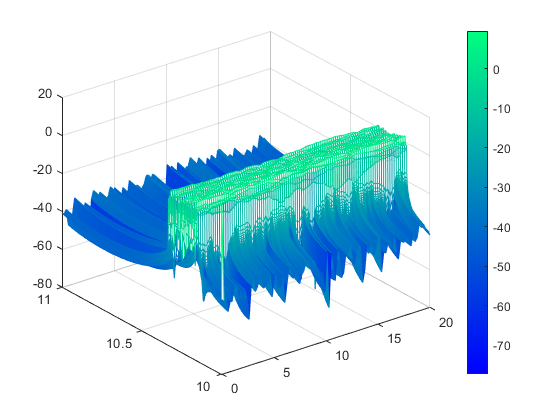

angleIndex = ceil(20*nth/360);
data = sigc(:,1:angleIndex); 
iData= ifft2(data,nf,angleIndex);
figure;
mesh(linspace(th1,20,angleIndex),linspace(fmin/1e9,fmax/1e9,nf),20*log10(abs(iData)));
colormap winter
colorbar

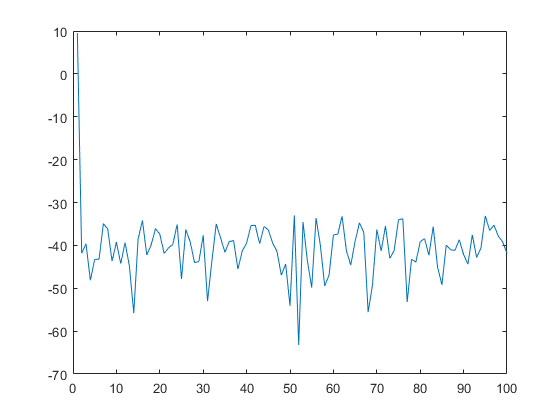


figure;
plot(20*log10(abs(iData(1,:))))